# Numerical methods - Lab 3

Name: Zhu Chenhao

HDU ID: 22320630

hwc = hwc_connect('https://dss2025.hdu.vedyakov.com');
task = hwc.get_task(3);

N = task.parameters.N;
T1 = task.parameters.T1;
T2 = task.parameters.T2;
a = task.parameters.a;
b = task.parameters.b;
c = task.parameters.c;
check_point_1 = task.parameters.check_point_1;
check_point_2 = task.parameters.check_point_2;
d = task.parameters.d;
init1 = task.parameters.init1;
init2 = task.parameters.init2;
m = task.parameters.m;
ode_num1 = task.parameters.ode_num1;
ode_num2 = task.parameters.ode_num2;
phi = task.parameters.phi;
r = task.parameters.r;
step1 = task.parameters.step1;
step2 = task.parameters.step2;
w = task.parameters.w;

## Part 1: Function of Exponents

%% Part 1: Function of Exponents
f = @(t, phi) derivative_phi(t, a, b, N);

% Use appropriate ODE solver based on ode_num1
if ode_num1 == 1
    [t_num, phi_num] = ode1(f, [0, T1], init1, step1);
elseif ode_num1 == 2
    [t_num, phi_num] = ode2(f, [0, T1], init1, step1);
elseif ode_num1 == 3
    [t_num, phi_num] = ode3(f, [0, T1], init1, step1);
elseif ode_num1 == 4
    [t_num, phi_num] = ode4(f, [0, T1], init1, step1);
else
    % Use MATLAB's built-in ODE solver (more efficient)
    options = odeset('RelTol',1e-6,'AbsTol',1e-9);
    [t_num, phi_num] = ode45(f, [0:step1:T1], init1, options);
    phi_num = phi_num';
end

phi_analytical = @(t) init1 + sum(a ./ b .* (1 - exp(-b * t)), 1);
phi_anal = phi_analytical(t_num);
phi_error = phi_anal(:) - phi_num(:);
error_value = phi_error(check_point_1 + 1);

% Store intermediate value for function_value_1
function_value_1 = phi_num(check_point_1 + 1);

% Part 2: Nonlinear System
u_func = @(t) interp1(t_num, phi_num, t, 'linear', 'extrap');
    
f_system = @(t, x) nonlinear_system(t, x, m, r, c, d, u_func);

% Use appropriate ODE solver based on ode_num2
if ode_num2 == 1
    [t_sys, x_sys] = ode1(f_system, [0, T2], init2, step2);
elseif ode_num2 == 2
    [t_sys, x_sys] = ode2(f_system, [0, T2], init2, step2);
elseif ode_num2 == 3
    [t_sys, x_sys] = ode3(f_system, [0, T2], init2, step2);
elseif ode_num2 == 4
    [t_sys, x_sys] = ode4(f_system, [0, T2], init2, step2);
else
    % Use MATLAB's built-in ODE solver (more efficient)
    options = odeset('RelTol',1e-6,'AbsTol',1e-9);
    [t_sys, x_sys] = ode45(f_system, [0:step2:T2], init2, options);
    x_sys = x_sys';
    t_sys = t_sys';
end

y = x_sys(:, 1);
function_value_2 = y(check_point_2 + 1);

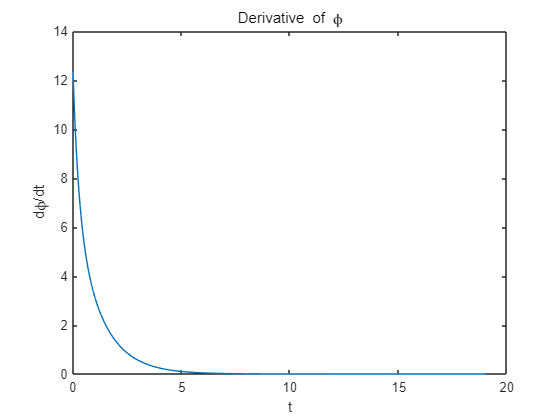

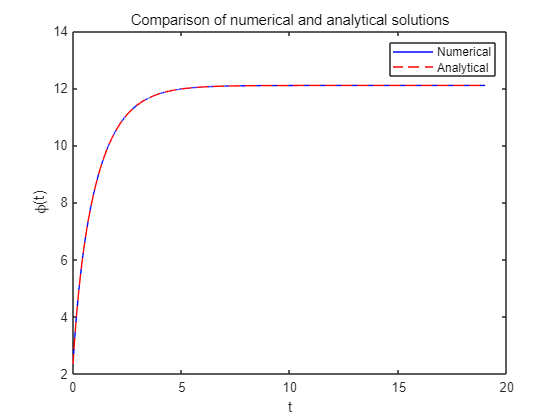

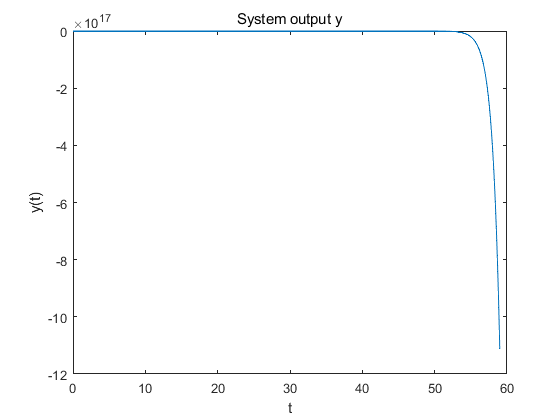

% Plotting (optional)
Uncomment these if you need the plots

figure;
t_plot = 0:0.01:T1;
dphi_plot = arrayfun(@(t) derivative_phi(t, a, b, N), t_plot);
plot(t_plot, dphi_plot);
title('Derivative of \phi');
xlabel('t');
ylabel('d\phi/dt');

figure;
plot(t_num, phi_num, 'b-', t_num, phi_anal, 'r--');
legend('Numerical', 'Analytical');
title('Comparison of numerical and analytical solutions');
xlabel('t');
ylabel('\phi(t)');

figure;
plot(t_sys, y);
title('System output y');
xlabel('t');
ylabel('y(t)');

## Answers

task.answers.error_value = error_value;
task.answers.function_value_1 = function_value_1;
task.answers.function_value_2 = function_value_2;
task.answers

ans = 包含以下字段的 struct :
         error_value: -3.7715e-10
    function_value_1: 12.0949
    function_value_2: -50.2497


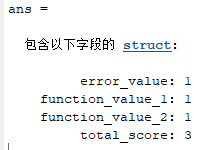

function dphi = derivative_phi(t, a, b, N)
    dphi = 0;
    for k = 1:N
        dphi = dphi + a(k) * exp(-b(k) * t);
    end
end

function dx = nonlinear_system(t, x, m, r, c, d, u)
    x1 = x(1); x2 = x(2);
    u_t = u(t);
    dx1 = x2;
    dx2 = (-d*abs(u_t) - r*x2 - c*x1;
    dx2 = dx2 / (m*(sin(x1) + 2));
    dx = [dx1; dx2];
end

% ODE solvers (kept for compatibility)
function [t, y] = ode1(f, tspan, y0, h)
    t = tspan(1):h:tspan(2);
    y = zeros(length(t), length(y0));
    y(1,:) = y0;
    for i = 1:length(t)-1
        y(i+1,:) = y(i,:) + h * f(t(i), y(i,:))';
    end
end

function [t, y] = ode2(f, tspan, y0, h)
    t = tspan(1):h:tspan(2);
    y = zeros(length(t), length(y0));
    y(1,:) = y0;
    for i = 1:length(t)-1
        k1 = f(t(i), y(i,:))';
        k2 = f(t(i) + (2/3)*h, y(i,:) + (2/3)*h*k1)';
        y(i+1,:) = y(i,:) + h*((1/4)*k1 + (3/4)*k2);
    end
end

function [t, y] = ode3(f, tspan, y0, h)
    t = tspan(1):h:tspan(2);
    y = zeros(length(t), length(y0));
    y(1,:) = y0;
    for i = 1:length(t)-1
        K1 = f(t(i), y(i,:))';
        K2 = f(t(i) + 1/3*h, y(i,:) + 1/3*h*K1)';
        K3 = f(t(i) + 2/3*h, y(i,:) - 1/3*h*K1 + h*K2)';
        y(i+1,:) = y(i,:) + h*(1/4*K1 + 0*K2 + 3/4*K3);
    end
end

function [t, y] = ode4(f, tspan, y0, h)
    t = tspan(1):h:tspan(2);
    y = zeros(length(t), length(y0));
    y(1,:) = y0;
    for i = 1:length(t)-1
        K1 = f(t(i), y(i,:))';
        K2 = f(t(i) + h/3, y(i,:) + h/3*K1)';
        K3 = f(t(i) + 2*h/3, y(i,:) - h/3*K1 + h*K2)';
        K4 = f(t(i) + h, y(i,:) + h*K1 - h*K2 + h*K3)';
        y(i+1,:) = y(i,:) + h*(1/8*K1 + 3/8*K2 + 3/8*K3 + 1/8*K4);
    end
end